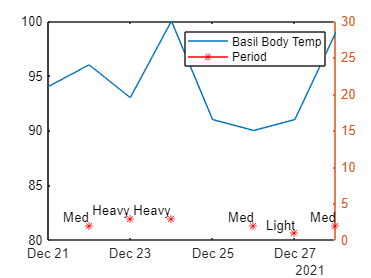

clf;
t = datetime(2021,12,21) + caldays(0:7);
temps = [];
periods = [];
labels = [("")]; 

for i = 1:length(t)
    temps = addTempData(temps, i);
    periods = addPeriodData(periods, i);
end 

plot(t, temps);
ylim([80 100])
hold on
yyaxis right
ylim([0 30])

for i = 1:length(periods)
    if periods(i) > 0
        plot(t(i), periods(i),'*-r')
        hold on
    end 
end 

for i = 1:length(periods)
    if periods(i) == 1
        labels(i) = "Light";
        text(t(i),periods(i),labels(i),'VerticalAlignment','bottom','HorizontalAlignment','right')
    end 
    if periods(i) == 2
        labels(i) = "Med";
         text(t(i),periods(i),labels(i),'VerticalAlignment','bottom','HorizontalAlignment','right')
    end 
    if periods(i) == 3
        labels(i) = "Heavy";
         text(t(i),periods(i),labels(i),'VerticalAlignment','bottom','HorizontalAlignment','right')
    end 
end 

legend("Basil Body Temp", "Period ")